Load the directories of training and testing sets.

testDir = 'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Test_Data'

testDir = 'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Test_Data'

trainDirBalanced = 'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Training_Data'

trainDirBalanced = 'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Training_Data'


TrainDir = 'D:\datasets\isic2016\unbalanced\ISBI2016_ISIC_Part3_Training_Data'

TrainDir = 'D:\datasets\isic2016\unbalanced\ISBI2016_ISIC_Part3_Training_Data'

Read the tables of both the train and testing ground truths, grabbing the image name and the corresponding diagnosis.


testGroundTruths = readtable("D:\datasets\isic2016\ISBI2016_ISIC_Part3_Test_GroundTruth.csv")

testGroundTruths = 379×2 table
          img             diagnosis  
    ________________    _____________

    {'ISIC_0000003'}    {'benign'   }
    {'ISIC_0000012'}    {'benign'   }
    {'ISIC_0000013'}    {'malignant'}
    {'ISIC_0000014'}    {'benign'   }
    {'ISIC_0000015'}    {'benign'   }
    {'ISIC_0000020'}    {'benign'   }
    {'ISIC_0000022'}    {'malignant'}
    {'ISIC_0000023'}    {'benign'   }
    {'ISIC_0000027'}    {'benign'   }
    {'ISIC_0000036'}    {'malignant'}
    {'ISIC_0000037'}    {'benign'   }
    {'ISIC_0000040'}    {'malignant'}
    {'ISIC_0000043'}    {'malignant'}
    {'ISIC_0000052'}    {'benign'   }
    {'ISIC_0000053'}    {'benign'   }
    {'ISIC_0000056'}    {'malignant'}


trainGroundTruthsBalanced = readtable("D:\datasets\isic2016\ISBI2016_ISIC_Part3_Training_GroundTruth.csv")

trainGroundTruthsBalanced = 1454×2 table
          img             diagnosis  
    ________________    _____________

    {'ISIC_0000000'}    {'benign'   }
    {'ISIC_0000001'}    {'benign'   }
    {'ISIC_0000002'}    {'malignant'}
    {'ISIC_0000004'}    {'malignant'}
    {'ISIC_0000006'}    {'benign'   }
    {'ISIC_0000007'}    {'benign'   }
    {'ISIC_0000008'}    {'benign'   }
    {'ISIC_0000009'}    {'benign'   }
    {'ISIC_0000010'}    {'benign'   }
    {'ISIC_0000011'}    {'benign'   }
    {'ISIC_0000016'}    {'benign'   }
    {'ISIC_0000017'}    {'benign'   }
    {'ISIC_0000018'}    {'benign'   }
    {'ISIC_0000019'}    {'benign'   }
    {'ISIC_0000021'}    {'benign'   }
    {'ISIC_0000024'}    {'benign'   }



trainGroundTruths = readtable("D:\datasets\isic2016\unbalanced\ISBI2016_ISIC_Part3_Training_GroundTruth.csv")

trainGroundTruths = 1454×2 table
          img             diagnosis  
    ________________    _____________

    {'ISIC_0000000'}    {'benign'   }
    {'ISIC_0000001'}    {'benign'   }
    {'ISIC_0000002'}    {'malignant'}
    {'ISIC_0000004'}    {'malignant'}
    {'ISIC_0000006'}    {'benign'   }
    {'ISIC_0000007'}    {'benign'   }
    {'ISIC_0000008'}    {'benign'   }
    {'ISIC_0000009'}    {'benign'   }
    {'ISIC_0000010'}    {'benign'   }
    {'ISIC_0000011'}    {'benign'   }
    {'ISIC_0000016'}    {'benign'   }
    {'ISIC_0000017'}    {'benign'   }
    {'ISIC_0000018'}    {'benign'   }
    {'ISIC_0000019'}    {'benign'   }
    {'ISIC_0000021'}    {'benign'   }
    {'ISIC_0000024'}    {'benign'   }


Load the training and testing images into a data store from their respective directories.


trainImdsBalanced = imageDatastore(trainDirBalanced, "IncludeSubfolders",true, "LabelSource","foldernames")

trainImdsBalanced =   ImageDatastore with properties:

                       Files: {
                              ' ...\datasets\isic2016\ISBI2016_ISIC_Part3_Training_Data\ISIC_0000000.jpg';
                              ' ...\datasets\isic2016\ISBI2016_ISIC_Part3_Training_Data\ISIC_0000001.jpg';
                              ' ...\datasets\isic2016\ISBI2016_ISIC_Part3_Training_Data\ISIC_0000002.jpg'
                               ... and 1451 more
                              }
                     Folders: {
                              'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Training_Data'
                              }
                      Labels: [ISBI2016_ISIC_Part3_Training_Data; ISBI2016_ISIC_Part3_Training_Data; ISBI2016_ISIC_Part3_Training_Data ... and 1451 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"   

testImds = imageDatastore(testDir, "IncludeSubfolders",true, "LabelSource","foldernames")

testImds =   ImageDatastore with properties:

                       Files: {
                              'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Test_Data\ISIC_0000003.jpg';
                              'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Test_Data\ISIC_0000012.jpg';
                              'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Test_Data\ISIC_0000013.jpg'
                               ... and 375 more
                              }
                     Folders: {
                              'D:\datasets\isic2016\ISBI2016_ISIC_Part3_Test_Data'
                              }
                      Labels: [ISBI2016_ISIC_Part3_Test_Data; ISBI2016_ISIC_Part3_Test_Data; ISBI2016_ISIC_Part3_Test_Data ... and 375 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
        


trainBalanced = imageDatastore(TrainDir, "IncludeSubfolders",true,"LabelSource","foldernames")

trainBalanced =   ImageDatastore with properties:

                       Files: {
                              ' ...\unbalanced\ISBI2016_ISIC_Part3_Training_Data\ISIC_0000000.jpg';
                              ' ...\unbalanced\ISBI2016_ISIC_Part3_Training_Data\ISIC_0000001.jpg';
                              ' ...\unbalanced\ISBI2016_ISIC_Part3_Training_Data\ISIC_0000002.jpg'
                               ... and 897 more
                              }
                     Folders: {
                              'D:\datasets\isic2016\unbalanced\ISBI2016_ISIC_Part3_Training_Data'
                              }
                      Labels: [ISBI2016_ISIC_Part3_Training_Data; ISBI2016_ISIC_Part3_Training_Data; ISBI2016_ISIC_Part3_Training_Data ... and 897 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"

Grab a single image from the train data store, the specific one grabbed does not matter. Extract the hog features from the image and decide which is the optimal cell size to use, larger cell sizes are used when more large-scale spacial information is needed.

img = readimage(trainImdsBalanced, 20);
% Extract HOG features and HOG visualization
[hog_2x2, vis2x2] = extractHOGFeatures(img,'CellSize',[2 2])

hog_2x2 = 1×2779308 single row vector
         0         0         0         0    0.1434    0.2701    0.2701    0.2701    0.0319    0.2491         0         0         0    0.0478    0.1690    0.2701    0.2701    0.2701         0         0         0         0    0.2701    0.2701    0.1459    0.1033    0.0229    0.1359         0    0.0053    0.0214    0.2701    0.2701    0.2701    0.0960    0.1493    0.3117         0         0         0         0    0.0673    0.2339    0.2873    0.3117    0.3117         0         0         0         0


vis2x2 = Visualization

   Type plot(vis2x2) to visualize.

   Read-only properties:
                CellSize: [2 2]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


[hog_4x4, vis4x4] = extractHOGFeatures(img,'CellSize',[4 4])

hog_4x4 = 1×689832 single row vector
    0.1989    0.0063    0.0084    0.0264    0.3670    0.3670    0.2929    0.2143    0.3254    0.3670    0.0144    0.0110    0.0177    0.0402    0.0227    0.0315    0.0269    0.3670    0.0228    0.0143    0.0139    0.1194    0.3670    0.0817    0.0295    0.0086    0.0106    0.0404    0.0280    0.0257    0.0209    0.1198    0.0174    0.0211    0.0205    0.0467    0.4861    0.0231    0.0176    0.0173    0.0049    0.0024    0.0022    0.0094    0.4861    0.4861    0.0076    0.0101    0.0019    0.0016


vis4x4 = Visualization

   Type plot(vis4x4) to visualize.

   Read-only properties:
                CellSize: [4 4]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


[hog_8x8, vis8x8] = extractHOGFeatures(img,'CellSize',[8 8])

hog_8x8 = 1×168696 single row vector
    0.3811    0.0362    0.0386    0.0927    0.3811    0.1621    0.1297    0.1011    0.3811    0.3811    0.0189    0.0110    0.0136    0.0370    0.0269    0.0441    0.0511    0.3811    0.0453    0.0287    0.0419    0.1394    0.3811    0.0671    0.0305    0.0349    0.0296    0.0407    0.0292    0.0155    0.0259    0.0526    0.0803    0.0812    0.0612    0.0467    0.4455    0.0313    0.0179    0.0354    0.0817    0.0678    0.0735    0.0788    0.4455    0.4455    0.0817    0.0585    0.0514    0.0584


vis8x8 = Visualization

   Type plot(vis8x8) to visualize.

   Read-only properties:
                CellSize: [8 8]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


[hog_16x16, vis16x16] = extractHOGFeatures(img, 'CellSize', [16 16])

hog_16x16 = 1×40320 single row vector
    0.3416    0.0680    0.0647    0.1223    0.3416    0.1563    0.1228    0.1090    0.3416    0.3416    0.1185    0.0741    0.0510    0.0666    0.0769    0.0530    0.0637    0.3416    0.0725    0.0796    0.1034    0.1740    0.3416    0.1474    0.0859    0.1047    0.0600    0.1192    0.1010    0.0858    0.0761    0.0846    0.1077    0.0923    0.1190    0.1012    0.3312    0.1568    0.0966    0.0585    0.0630    0.0690    0.0577    0.1034    0.3312    0.3312    0.1018    0.0861    0.0658    0.0973


vis16x16 = Visualization

   Type plot(vis16x16) to visualize.

   Read-only properties:
                CellSize: [16 16]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


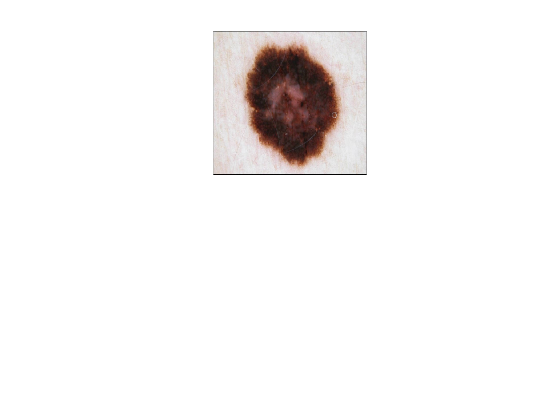


% Show the image
figure; 
subplot(2,3,1:3); 
imshow(img);

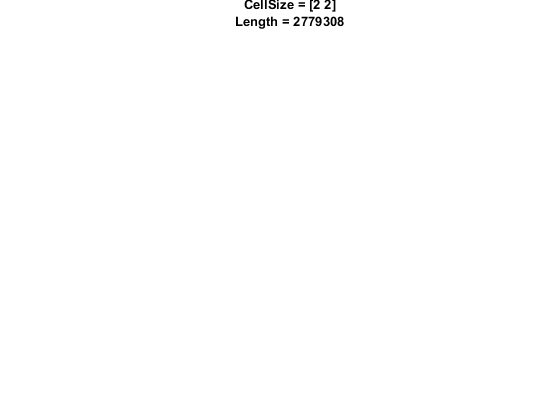

% Visualize the HOG features

plot(vis2x2); 
title({'CellSize = [2 2]'; ['Length = ' num2str(length(hog_2x2))]});

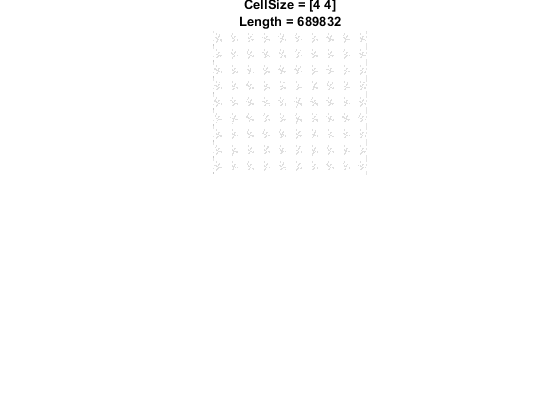

 

plot(vis4x4); 
title({'CellSize = [4 4]'; ['Length = ' num2str(length(hog_4x4))]});

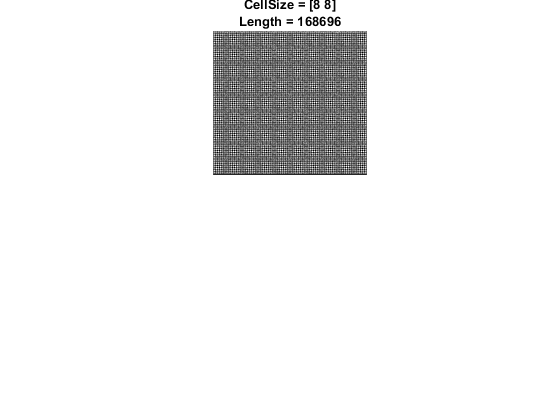


plot(vis8x8); 
title({'CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

Define the cell size to be used during HOG feature extraction

cellSize = [8 8]

cellSize =      8     8


hogFeatureSize = length(hog_8x8)

hogFeatureSize = 168696

Loop over the training set and extract HOG features from each image . A similar procedure will be used to for the test set later on. This snippet deals with the balanced training data.


%get number of images in the image datastore
numImagesTrain = numel(trainImdsBalanced.Files)

numImagesTrain = 1454

trainingFeaturesBalanced = zeros(numImagesTrain, hogFeatureSize, 'single');
trainingLabelsBalanced = categorical(trainGroundTruthsBalanced{:,2})

trainingLabelsBalanced = 1454×1 categorical array
     benign 
     benign 
     malignant 
     malignant 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     benign 
     malignant 
     benign 
     malignant 
     malignant 
     malignant 
     benign 
     benign 
     malignant 
     benign 
     benign 
     benign 
     benign 
     benign 




for i = 1:numImagesTrain
    img = readimage(trainImdsBalanced, i);
    
   [rows, cols, numChannels] = size(img);
%     if (numChannels > 1)
%         img = rgb2gray(img);
%     end
    
% %     img = imresize(img, [209, 191] )
    % Apply pre-processing steps
    img = imbinarize(img);
    
    trainingFeaturesBalanced(i, :) = extractHOGFeatures(img, 'CellSize', cellSize);  
end

% Get labels for each image.

This snippet deals with the unbalanced training data.

%get number of images in the image datastore
numImagesTrain = numel(trainImds.Files)

Unable to resolve the name trainImds.Files.

trainingFeatures = zeros(numImagesTrain, hogFeatureSize, 'single');
trainingLabels = categorical(trainGroundTruths{:,2})


for i = 1:numImagesTrain
    img = readimage(trainImds, i);
    
   [rows, cols, numChannels] = size(img);
%     if (numChannels > 1)
%         img = rgb2gray(img);
%     end
    
% %     img = imresize(img, [209, 191] )
    % Apply pre-processing steps
    img = imbinarize(img);
    
    trainingFeatures(i, :) = extractHOGFeatures(img, 'CellSize', cellSize);  
end

countcats(trainingLabels)


Create an SVM template which grants greater flexibility in controlling the parameters of the model. Predictor data is standardised meaning each column is centred and scaled by the weighted column mean and standard deviation. 

The classifier is then trained using the fit method, passing in the training data and the template SVM. Hyperparameter optimisation attempts to minimise the cross-validation loss by varying the parameters, this considerably adds to compute time. 

t = templateSVM('Standardize', true, 'KernelFunction', 'rbf')

classifierLinear = fitclinear(trainingFeaturesBalanced, trainingLabelsBalanced)
% classifierSVMOptHyp = fitcsvm(trainingFeatures, trainingLabels, 'OptimizeHyperparameters',"all")
classifierSVM = fitcsvm(trainingFeaturesBalanced, trainingLabelsBalanced)

classifierSVMUnbalanced = fitcsvm(trainingFeatures, trainingLabels)

% v0 = visualise_svm(classifier, trainingFeatures, trainingLabels)

% classifier.BinaryLoss
% classifier.ClassNames
% classifier.BinaryLearners{1}   % The first binary learner

% 
% codingMat = classifier.CodingMatrix
% error = resubLoss(classifier)

Similar to the above procedure whereby HOG features are extracted from the test image set. 

numImagesTest = numel(testImds.Files)
testingFeatures = zeros(numImagesTest, hogFeatureSize, 'single');
testLabels = categorical(testGroundTruths{2:1:end,2});

for i = 1:numImagesTest
    img = readimage(testImds, i);
    
   [rows, cols, numChannels] = size(img);
%     if (numChannels > 1)
%         img = rgb2gray(img);
%     end
    
    % Apply pre-processing steps
    img = imbinarize(img);
    
    testingFeatures(i, :) = extractHOGFeatures(img, 'CellSize', cellSize);  
end



Metrics for the standard linear SVM

predictionsLinear = predict(classifierLinear, testingFeatures);
[cLinear,orderLinear] = confusionmat(testLabels, predictionsLinear);
chartLinear = confusionchart(cLinear, orderLinear)
[senLinear, specLinear, accLinear, f1Linear, pLinear] = calcMetrics(cLinear)

Metrics for the standard non linear SVM

predictionsSVM = predict(classifierSVM, testingFeatures);
[cSVM,orderSVM] = confusionmat(testLabels, predictionsSVM);
chartSVM = confusionchart(cSVM, orderSVM)
[senSVM, specSVM, accSVM, f1SVM, pSVM] = calcMetrics(cSVM)

Metrics for the unbalanced varient of the standard SVM classifier

predictionsSVMUnbalanced = predict(classifierSVMUnbalanced, testingFeatures);
[cSVMUnbalanced,orderSVMUnbalanced] = confusionmat(testLabels, predictionsSVMUnbalanced);
chartSVM = confusionchart(cSVMUnbalanced, orderSVMUnbalanced)
[senSVMUnbalanced, specSVMUnbalanced, accSVMUnbalanced, f1SVMUnbalanced, pSVMUnbalanced] = calcMetrics(cSVMUnbalanced)

function [sensitivity, specificity, accuracy, f1, p] = calcMetrics(c) 

    p = sum(diag(c)) / sum(c(1:1:end));
    

    sensitivity = c(1,1) / (c(1,1) + c(1,2));
    specificity = c(2,2) / (c(2,2) + c(2,1));
    accuracy = (c(1,1) + c(2,2)) /(c(1,1) + c(2,2) + c(2,1) + c(1,2));
    % jaccard_similiarity_index = c(1,1) / (c(1,1) + c(1,2) + c(2,1))
    % dice_similarity_coefficient = 2 * c(1,1) / (2 * c(1,1) + c(1,2) + c(2,1))
    f1 = c(1,1) / c(1,1) + 0.5 * (c(2,1) + c(1,2));
end

function v = visualise_svm(m, examples, labels)

    % Hint: for any model, m, trained with fitcsvm(),
    % you can access the data used to train it with:
    m.X
    m.Y
    
    % Add as many lines of code as you need below:
    xmin = min(m.X{:,1});
    ymin = min(m.X{:,2});
    
    xmax = max(m.X{:,1});
    ymax = max(m.X{:,2});
    
    grid = [];
    counter =1;
    for i = xmin : 0.10 : xmax
         for j = ymin : 0.10 : ymax
        %the value of the outer loop (x) is stored in the first column
        grid(counter,1) = i;
        %inner loop(y) is stored in the second column
        grid(counter,2) = j;
        %increment to make sure the row numbers begin at 1 and go from
        %there
        counter = counter + 1;
    end
    %incremment the counter for the x axis 
    counter = counter + 1;
    end
    predictions = predict(m, grid);
  %retain the plot points
    hold on
    %plot the linear separator line using the grid generated previously 
    gscatter(grid(:,1), grid(:,2), predictions)
    hold off
    %superimose the original data ontop of the 
    hold on
    v = gscatter(examples{:,1}, examples{:,2}, labels);
    hold off
end